# Beispiel Maschenstromverfahren

Bsp 26

clear

R1=25, R2=45, R3=40, R4=35, R5=30

R1 = 25

R2 = 45

R3 = 40

R4 = 35

R5 = 30

U1=36, U2=30, U3=24, U4=12

U1 = 36

U2 = 30

U3 = 24

U4 = 12



Z = [ R1+R2    -R2         0
       -R2     R2+R3+R4   -R4   
        0       -R4         R4+R5 ]

Z =     70   -45     0
   -45   120   -35
     0   -35    65



U = [ U1-U2
      U2-U3-U4
       U4]

U =      6
    -6
    12





I = Z \ U

I =     0.1242
    0.0598
    0.2168



I1 = I(1)

I1 = 0.1242

I2 = I(2) - I(1)

I2 = -0.0644

I3 = I(2)

I3 = 0.0598

I4 = I(3) - I(2)

I4 = 0.1570

I5 = I(3)

I5 = 0.2168


UR1=I1*R1

U1 = 3.1038

UR2=I2*R2

U2 = -2.8962

UR3=I3*R3

U3 = 2.3918

UR4=I4*R4

U4 = 5.4956

UR5=I5*R5

U5 = 6.5044

## Gleiches Bsp mit Knotenpotentialverfahren

clear   

R1=25, R2=45, R3=40, R4=35, R5=30

R1 = 25

R2 = 45

R3 = 40

R4 = 35

R5 = 30

U1=36, U2=30, U3=24, U4=12

U1 = 36

U2 = 30

U3 = 24

U4 = 12


Iq1= U1/R1

Iq1 = 1.4400

Iq2= U2/R2

Iq2 = 0.6667

Iq3= U3/R3

Iq3 = 0.6000

Iq4= U4/R4

Iq4 = 0.3429



Y = [ 1/R1+1/R2+1/R3        -1/R3
        -1/R3                1/R3+1/R4+1/R5 ]

Y =     0.0872   -0.0250
   -0.0250    0.0869



I = [Iq1+Iq2+Iq3
     -Iq3+Iq4]

I =     2.7067
   -0.2571


    
U = Y\I

U =    32.8962
    6.5044




I5= U(2) / R5

I5 = 0.2168

## Matlab mit Plot

Bsp. B13
U = 12;
RP = 10;
RL = 6;

a = 0:1e-6:1

a =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



R1 = (1-a)*RP

R1 =    10.0000   10.0000   10.0000   10.0000   10.0000   10.0000    9.9999    9.9999    9.9999    9.9999    9.9999    9.9999    9.9999    9.9999    9.9999    9.9999    9.9998    9.9998    9.9998    9.9998    9.9998    9.9998    9.9998    9.9998    9.9998    9.9997    9.9997    9.9997    9.9997    9.9997    9.9997    9.9997    9.9997    9.9997    9.9997    9.9996    9.9996    9.9996    9.9996    9.9996    9.9996    9.9996    9.9996    9.9996    9.9996    9.9996    9.9995    9.9995    9.9995    9.9995


R2 = a * RP

R2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005



R2L = R2.*RL ./ (R2+RL)

R2L =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


UL = U * R2L ./ (R1+R2L)

UL =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006



IL = UL ./ RL

IL =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


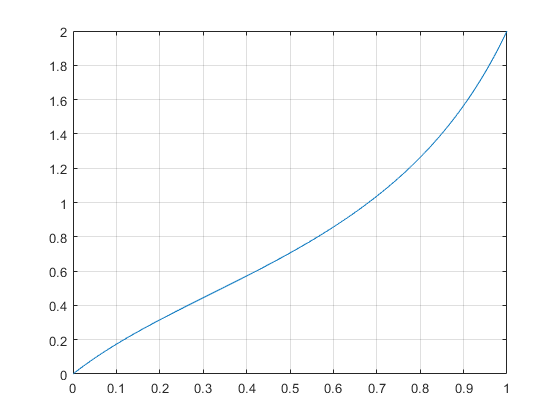




plot(a,IL), grid

## Programmierung approx annäherung while mit delta I < 0.0001